%Scripting to run PCA on hall of fame parameters from 05.12 B+S cloud model
clear
clc
PathToParams = '/Users/danielchapman/Desktop/PyrOptResults/11.24/Results/1000MSGenTestHofParams.csv';
HFParams = load(PathToParams);

PathToParams = '/Users/danielchapman/Desktop/PyrOptResults/11.22/Results/1000MSGenTestHofParams.csv';
ShamParams = load(PathToParams);

PathToFeats = '/Users/danielchapman/Desktop/PyrOptResults/11.24/Results/1000MSGenTestHofFeatures.csv';
HFFeats = load(PathToFeats);
%% Normalize each parameter to it's SD
HFFeats(19,:) = [];

PathToFeats = '/Users/danielchapman/Desktop/PyrOptResults/11.22/Results/1000MSGenTestHofFeatures.csv';
ShamFeats = load(PathToFeats);
%% Normalize each parameter to it's SD
ShamFeats(19,:) = [];

Params = [ShamParams HFParams];
ShamNum = length(ShamParams(1,:));
labels(1:ShamNum) = 1;
labels(ShamNum+1:length(Params(1,:))) = 0;

Feats = [ShamFeats HFFeats];

% Calculate slope of frequency and rheo
StimIntensity = [0.18 0.16 0.14 0.12 0.1 0.08 0.06 0.04 0.02];
for i = 1:length(Feats(1,:))
    SlopeVec = [Feats(1,i) Feats(8,i) Feats(10,i)...
        Feats(12,i) Feats(14,i) Feats(16,i) Feats(18,i)...
        Feats(20,i) Feats(21,i)];
    p = polyfit(StimIntensity,SlopeVec,1);
    Feats(24,i) = abs(p(1,1));
    Rheo = find(SlopeVec==0,1,'first');
    Feats(25,i) = StimIntensity(Rheo);
end

%
for i = 1:length(Params(:,1))
    [Z_Params, mu, sigma] = zscore(Params');
    STD = std(Params(i,:));
    NormParams(i,:) = Params(i,:)./STD;
end

for i = 1:length(ShamParams(:,1))
    [ShamZ_Params, Shammu, Shamsigma] = zscore(ShamParams');
    ShamSTD = std(ShamParams(i,:));
%     NormParams(i,:) = Params(i,:)./STD;
end

for i = 1:length(Feats(:,1))
    [Z_Feats, Feats_mu, Feats_sigma] = zscore(Feats);
    STD = std(Feats(i,:));
    NormFeats(i,:) = Feats(i,:)./STD;
end



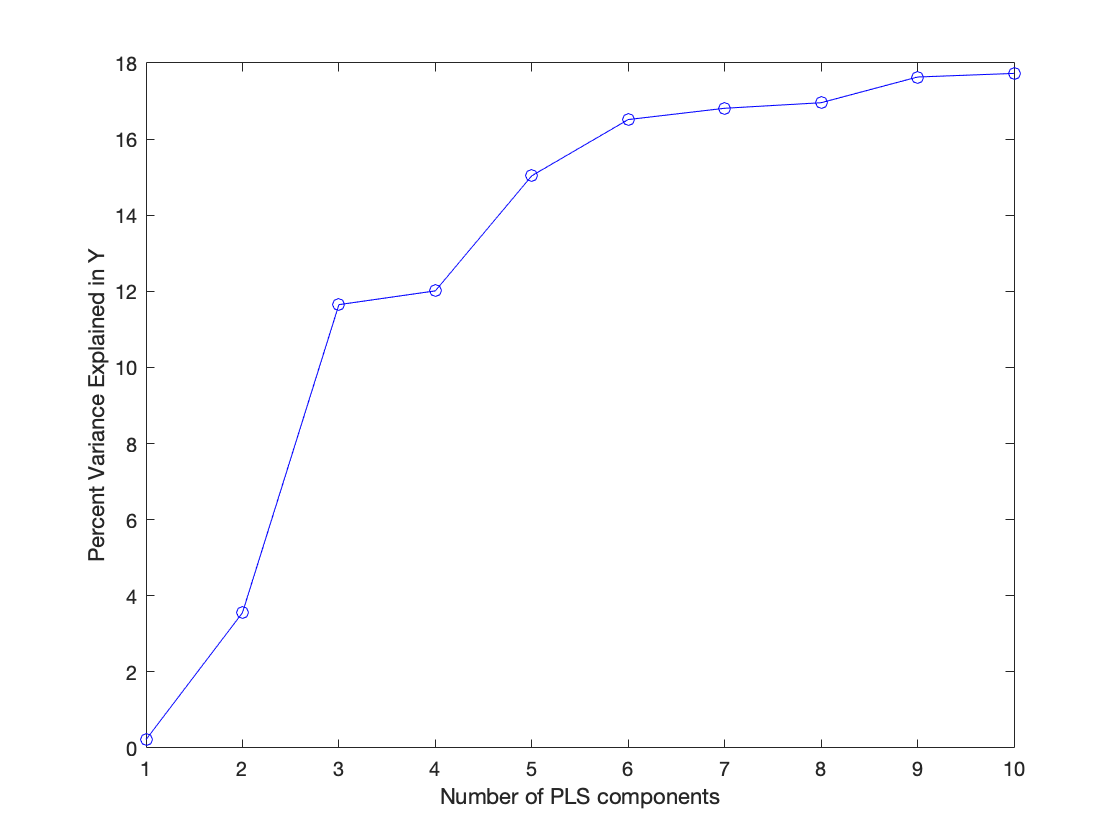

NumParams = length(Params(:,1));

%%
[coeff,score,latent,tsquared,explained,mu] = pca(Z_Params);
[Xloadings,Yloadings,Xscores,Yscores,betaPLS,PLSPctVar,blah,stats] = plsregress(((Z_Params-mu)./sigma),Feats(:,:)');
plot(1:NumParams,cumsum(100*PLSPctVar(2,:)),'-bo');
xlabel('Number of PLS components');
ylabel('Percent Variance Explained in Y');

% figure
% % subplot(7,1,1);
% bar(betaPLS(2:end,1));
% % subplot(7,1,2);
% figure
% bar(betaPLS(2:end,8));
% % subplot(7,1,3);
% figure
% bar(betaPLS(2:end,10));
% % subplot(7,1,4);
% figure
% bar(betaPLS(2:end,12));
% % subplot(7,1,5);
% figure
% bar(betaPLS(2:end,14));
% % subplot(7,1,6);
% figure
% bar(betaPLS(2:end,16));
% % subplot(7,1,7);
% figure
% bar(betaPLS(2:end,20));
% figure 
% bar(betaPLS(2:end,23));
% figure 
% bar(betaPLS(2:end,24));
% figure 
% bar(betaPLS(2:end,25));

% [coeff,score,latent,tsquared,explained,mu] = pca(NormParams');

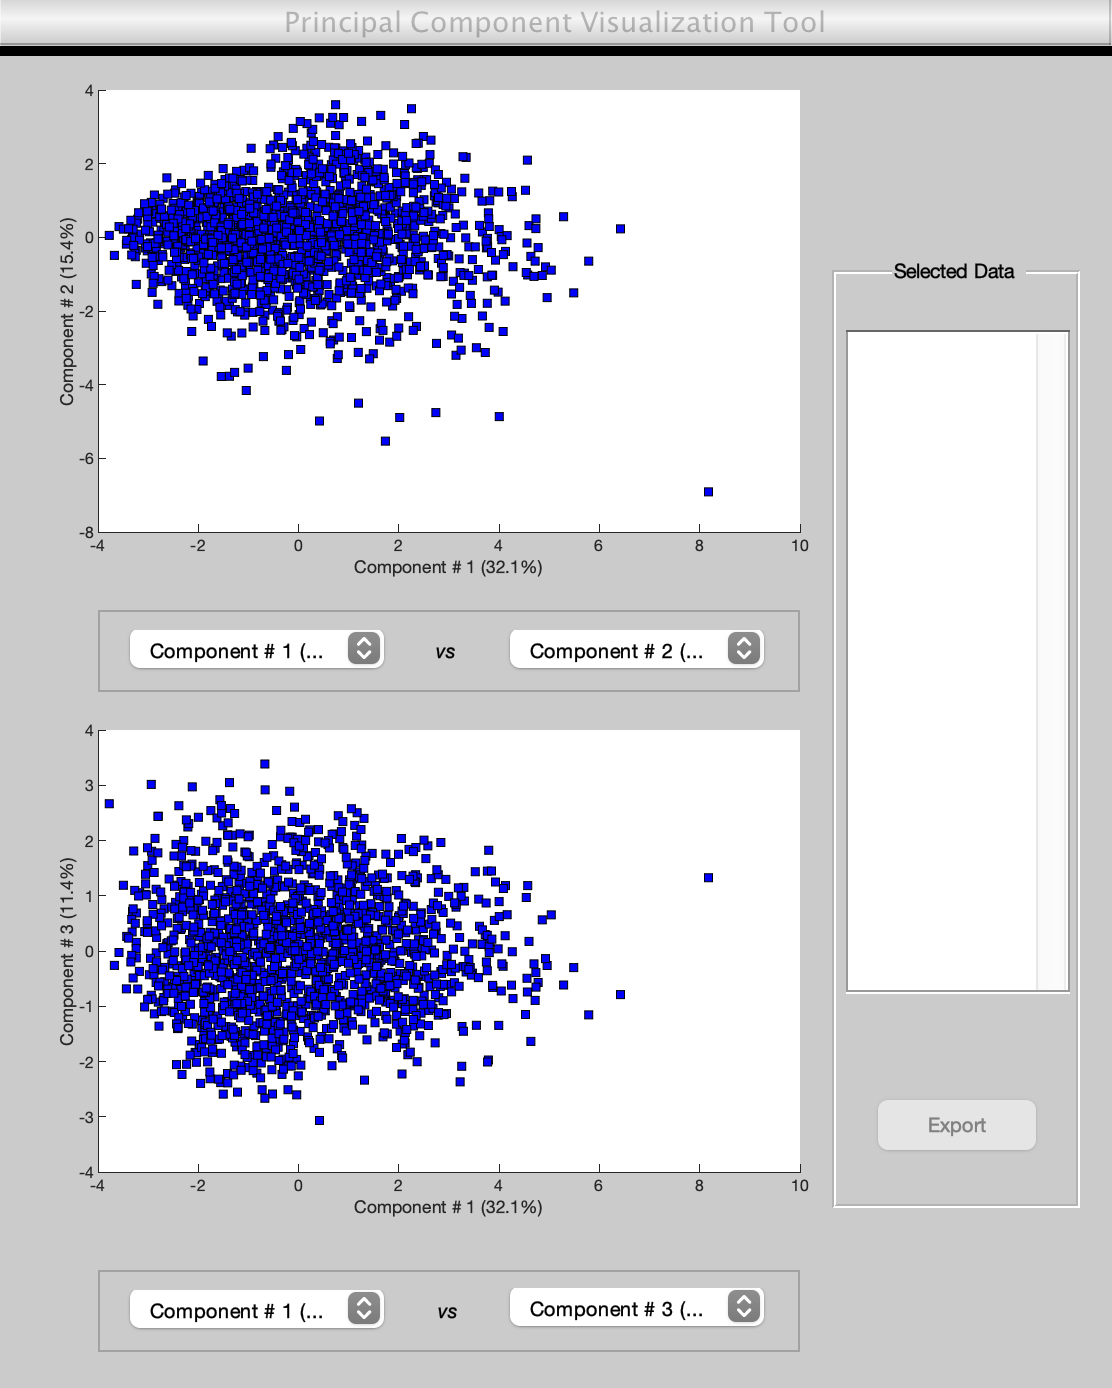

% 
% %%
% Xcentered = score.*coeff;
mapcaplot(Z_Params,labels)

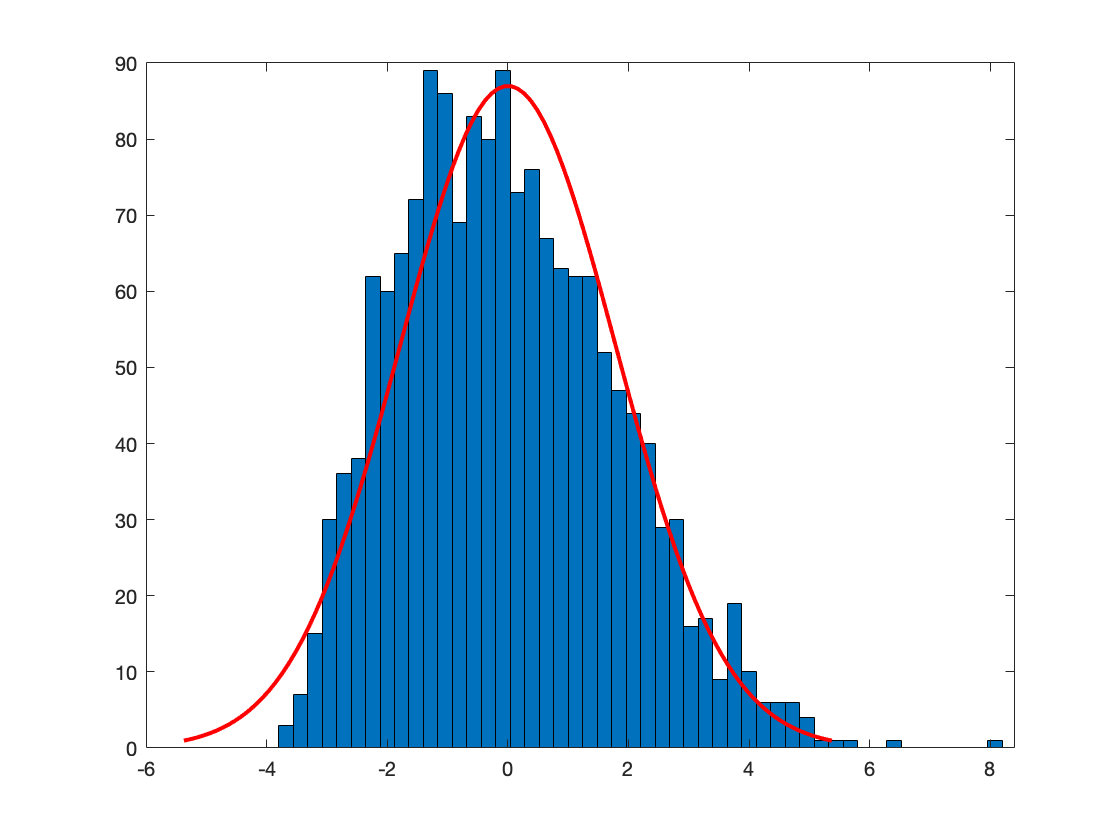

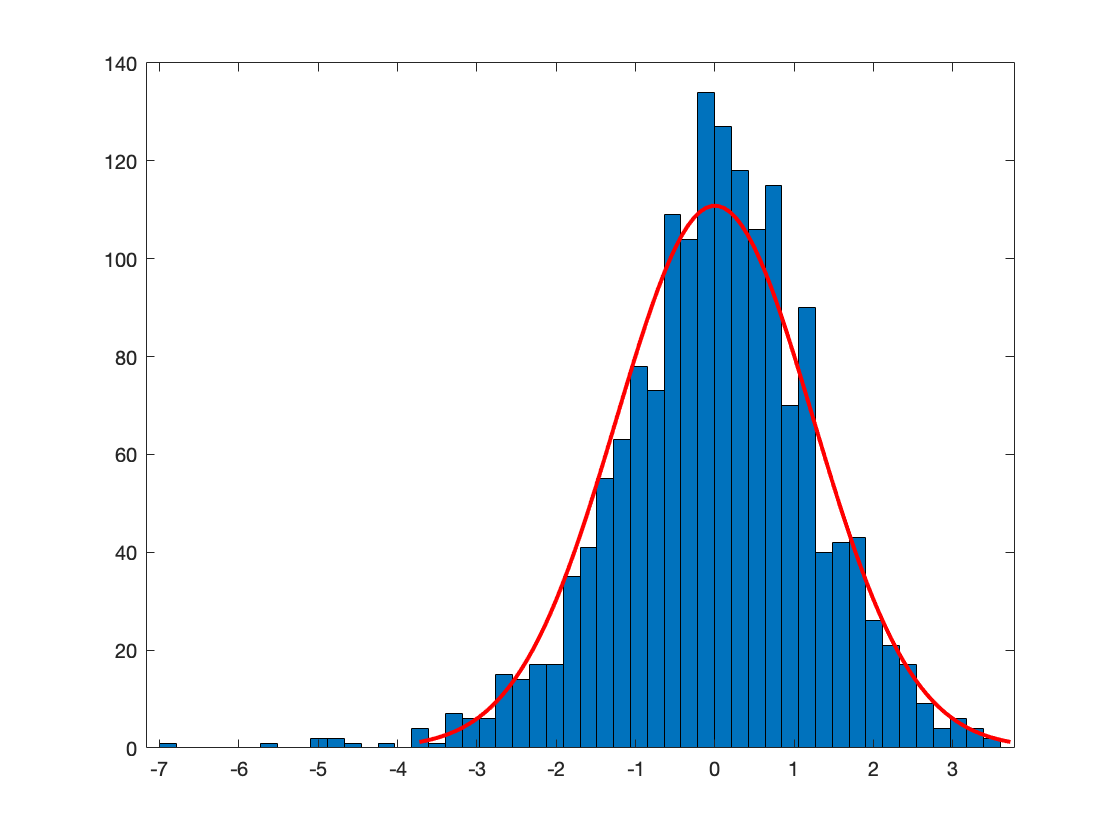

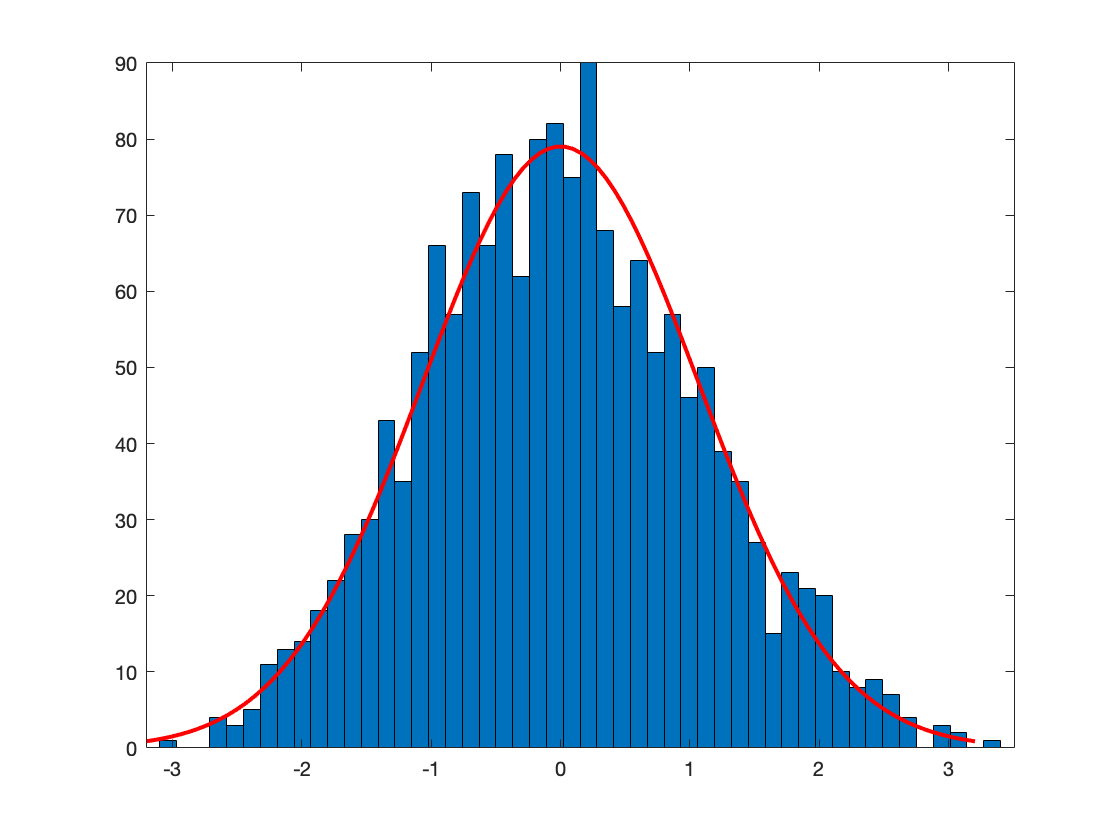

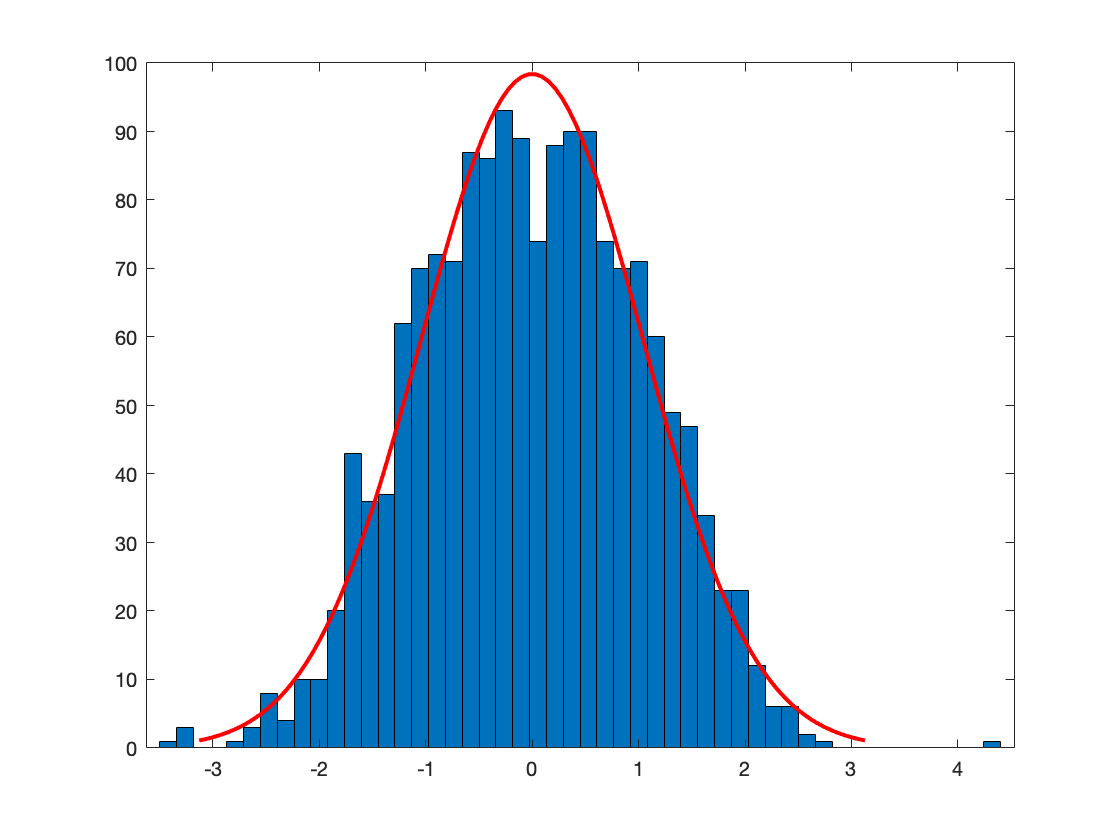

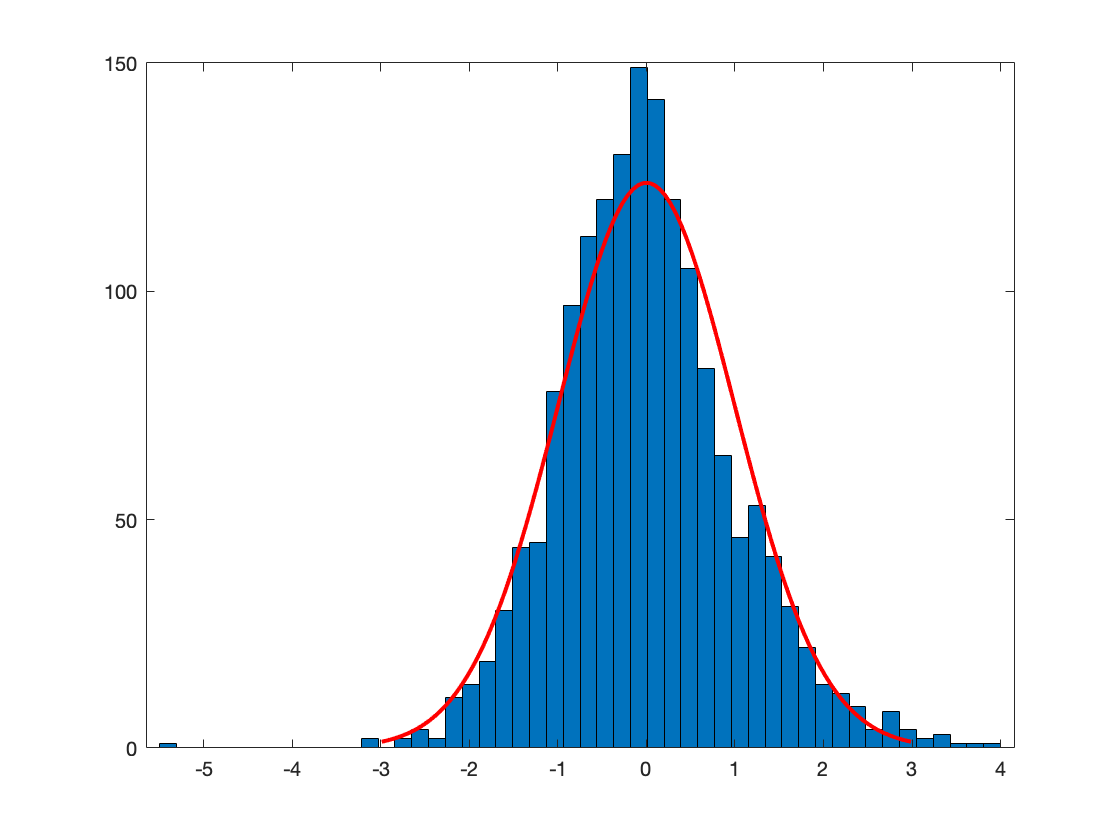

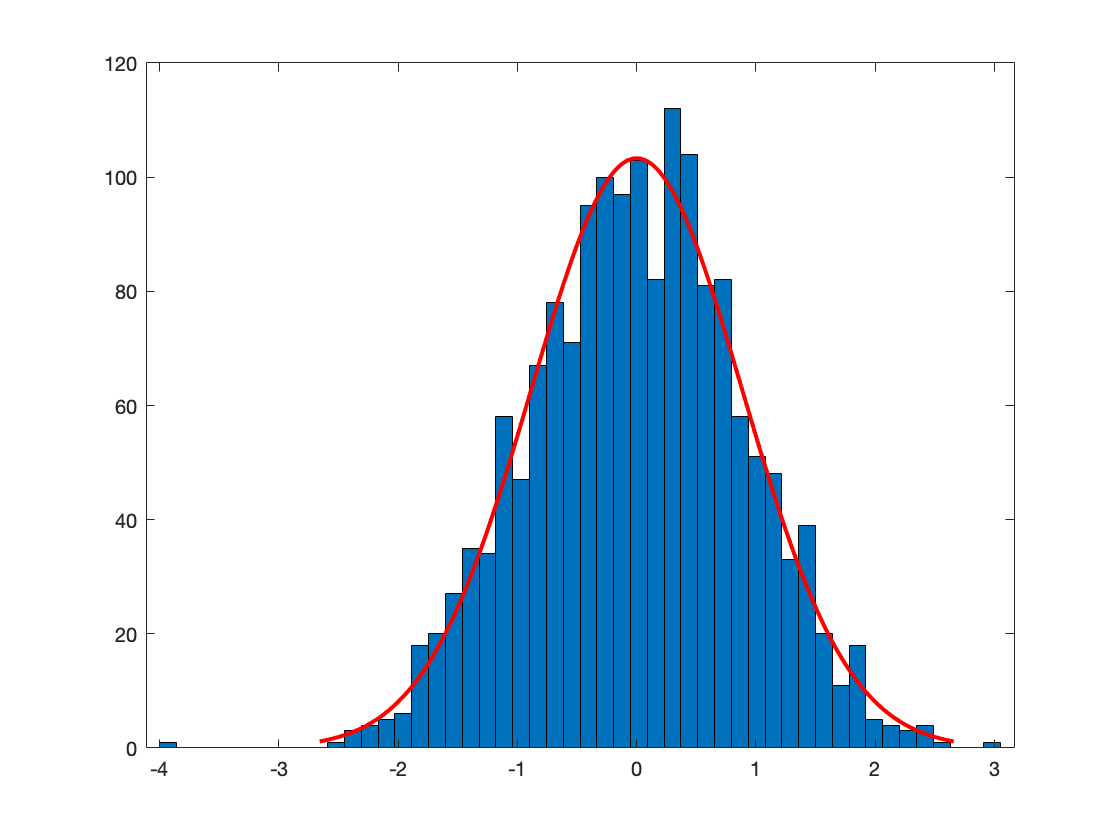

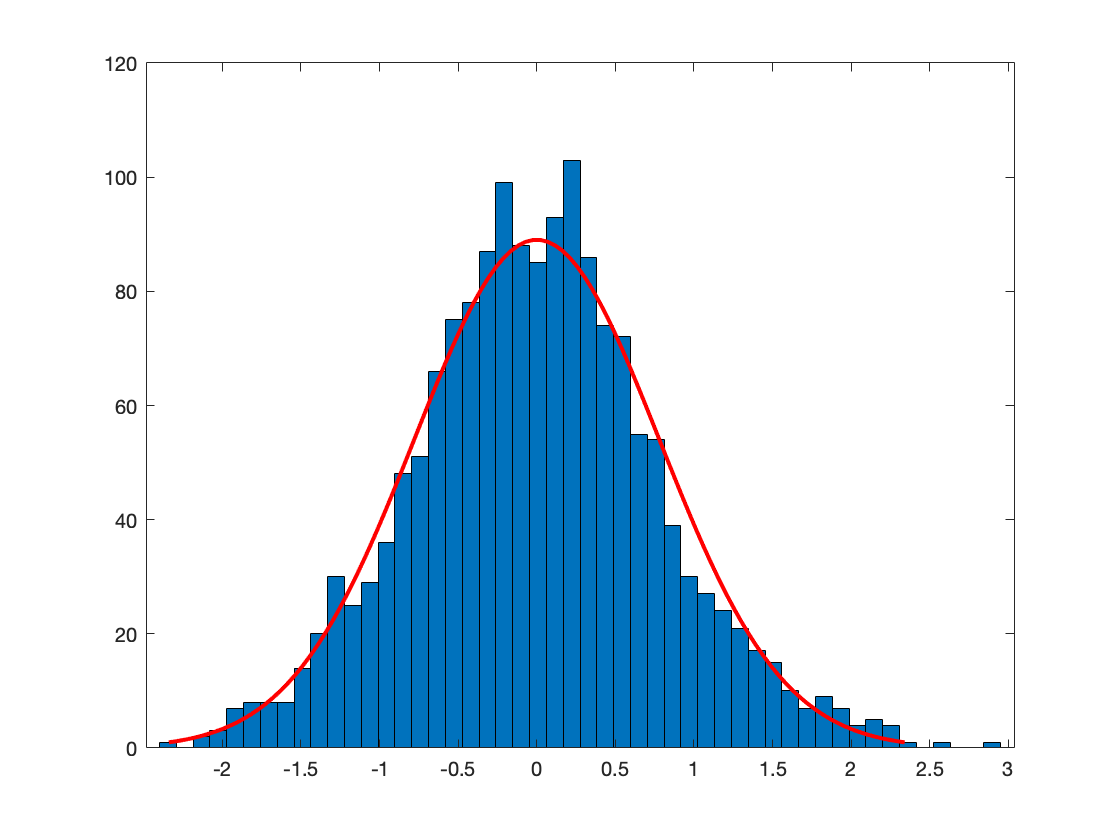

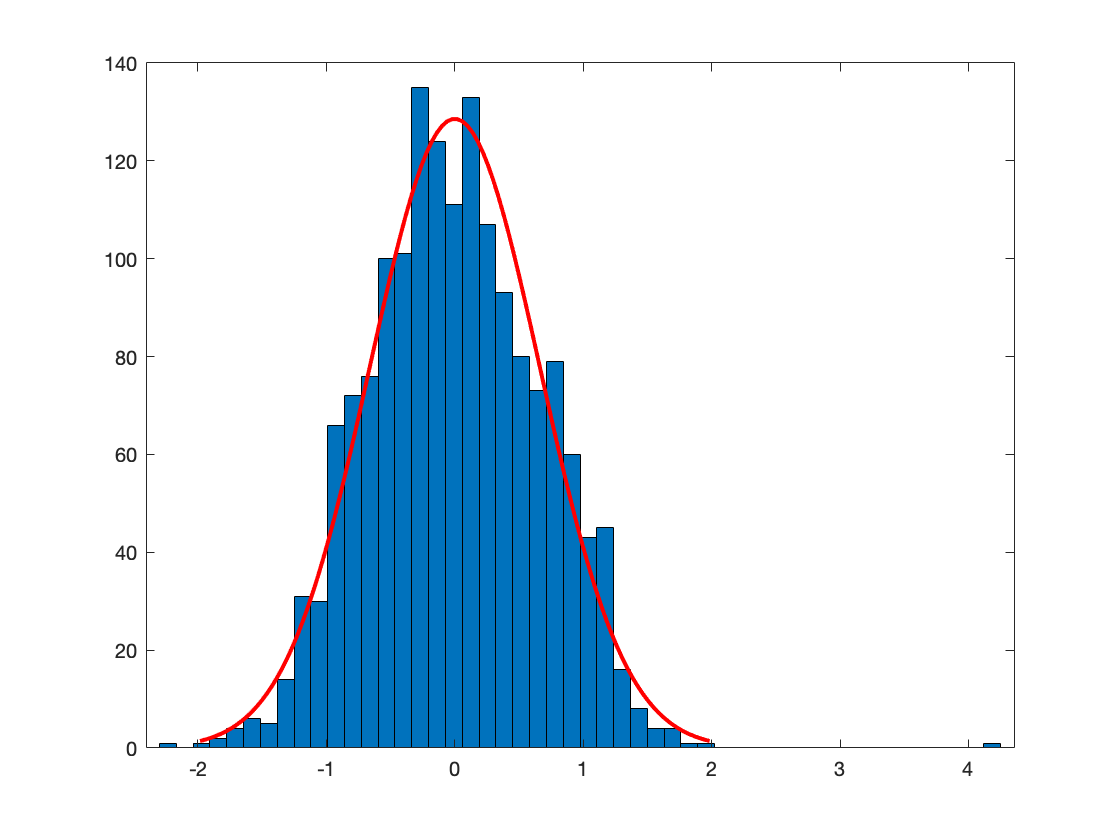

[coeff,score,latent,tsquared,explained,mu] = pca(Z_Params);
%%
for i = 1:length(score(1,:))
    figure
    histfit(score(:,i),50)
end

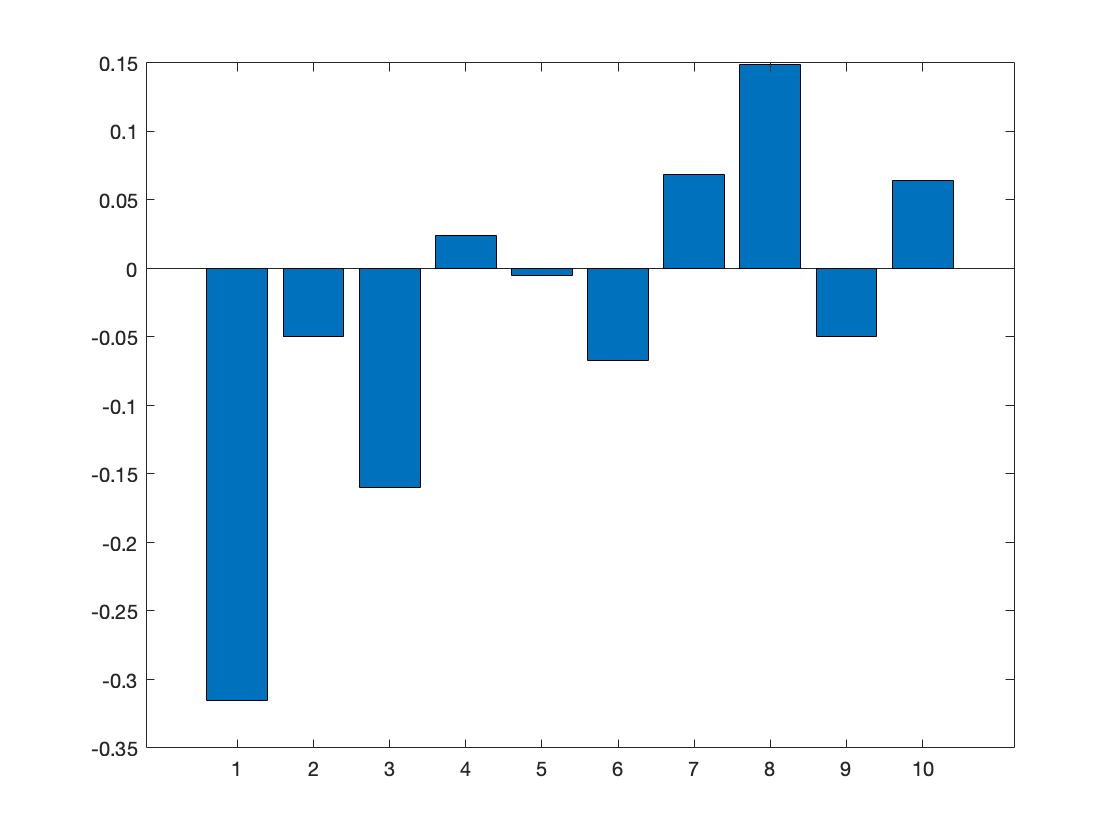

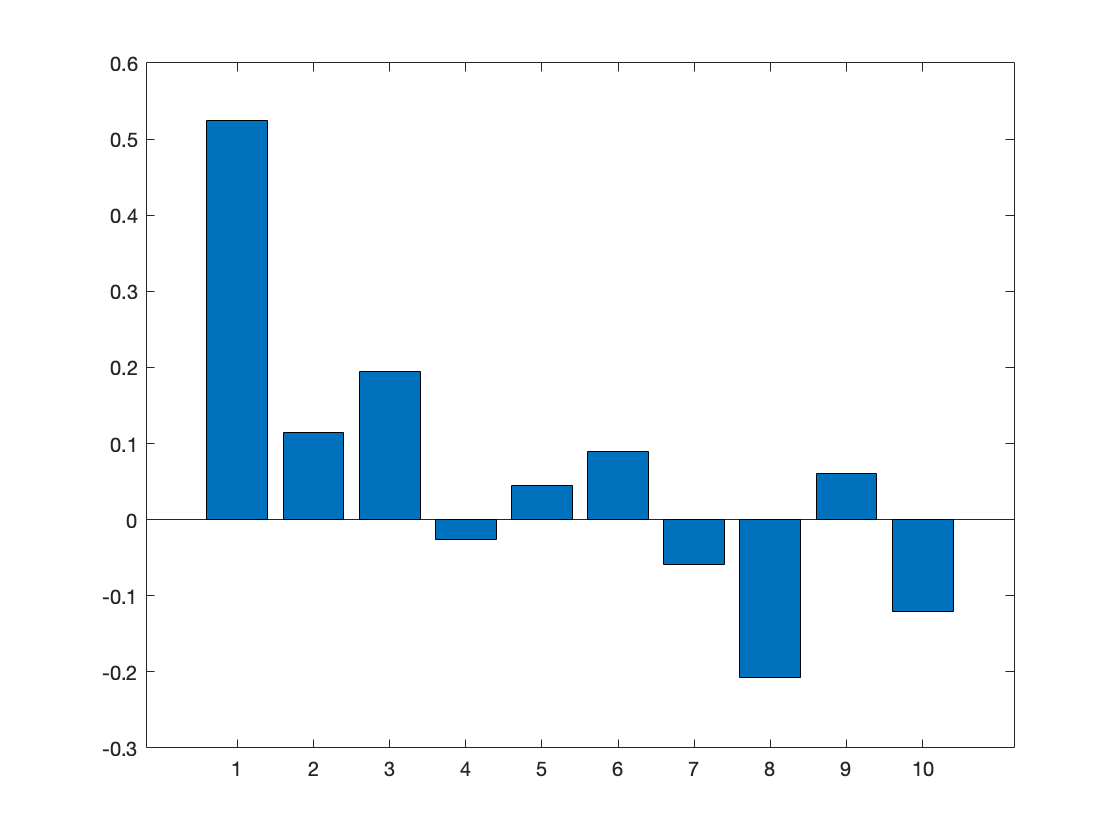

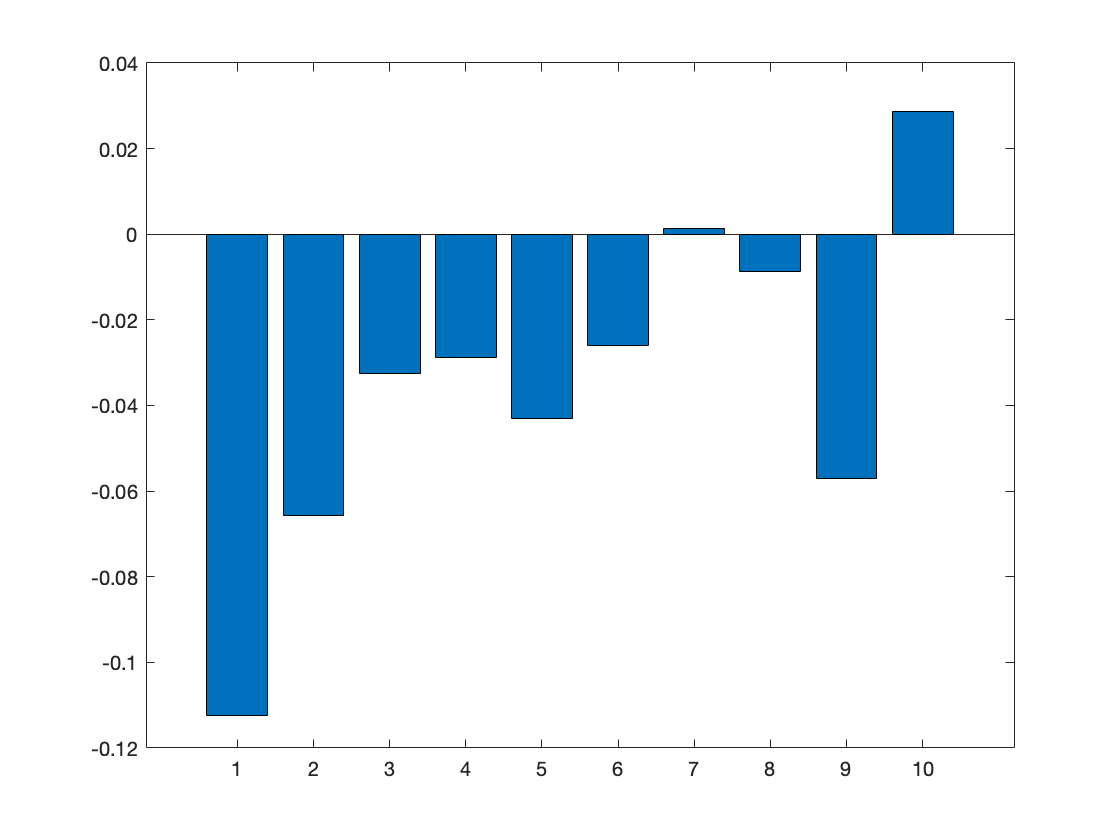

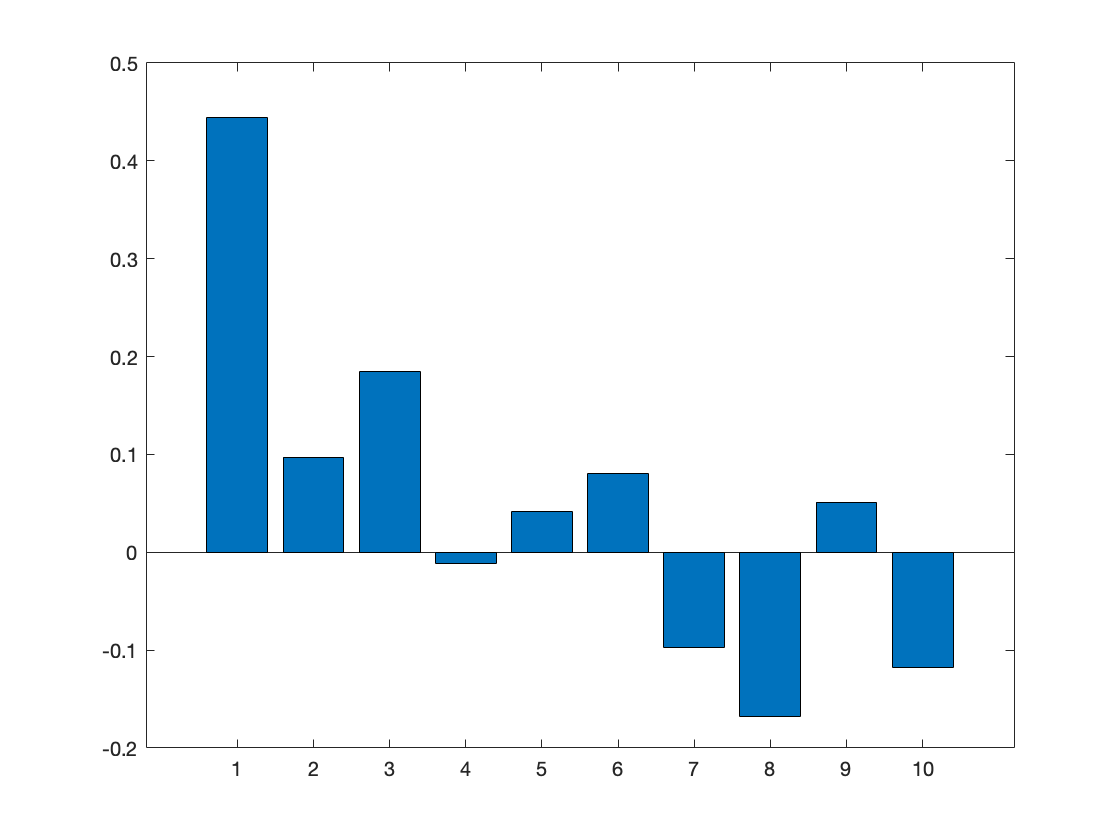

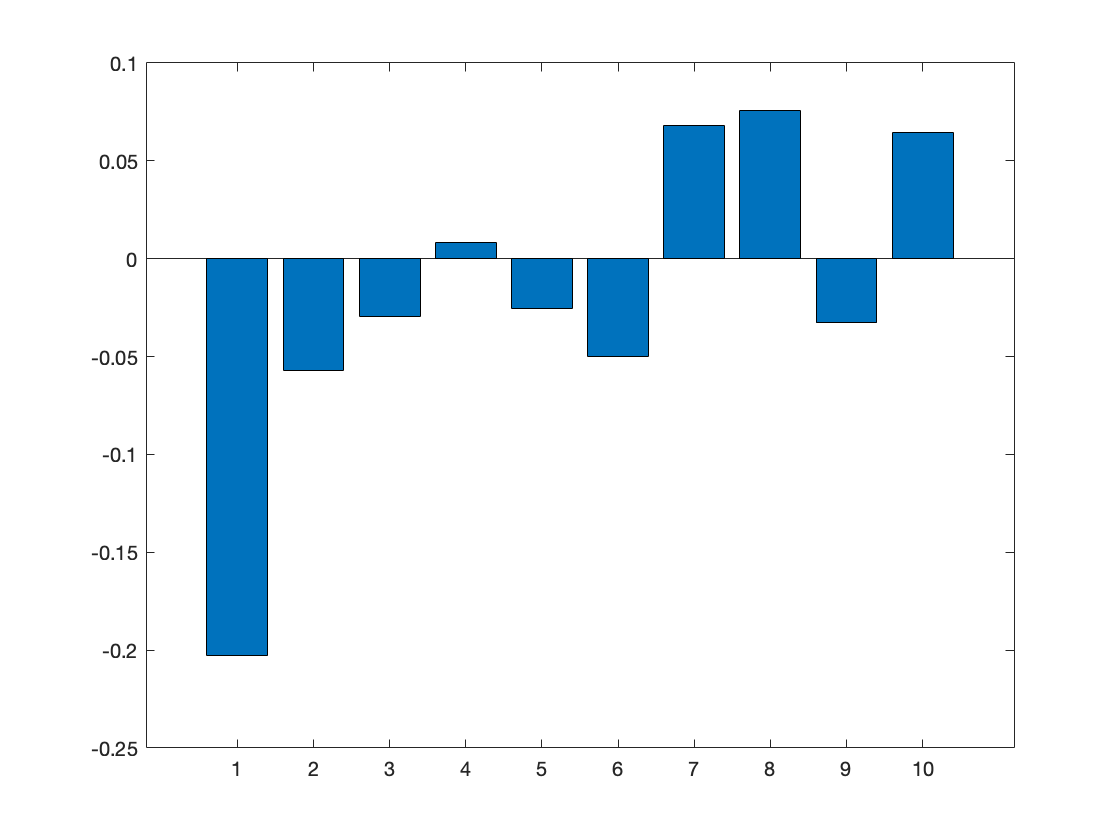

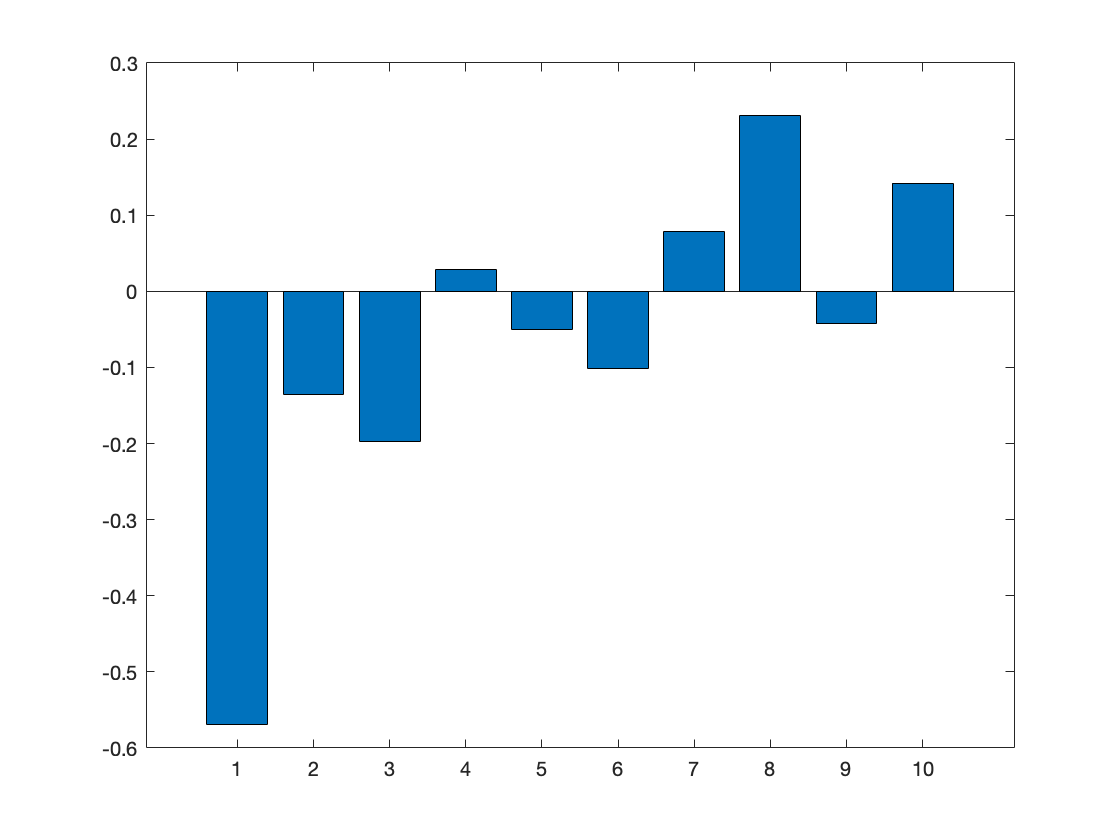

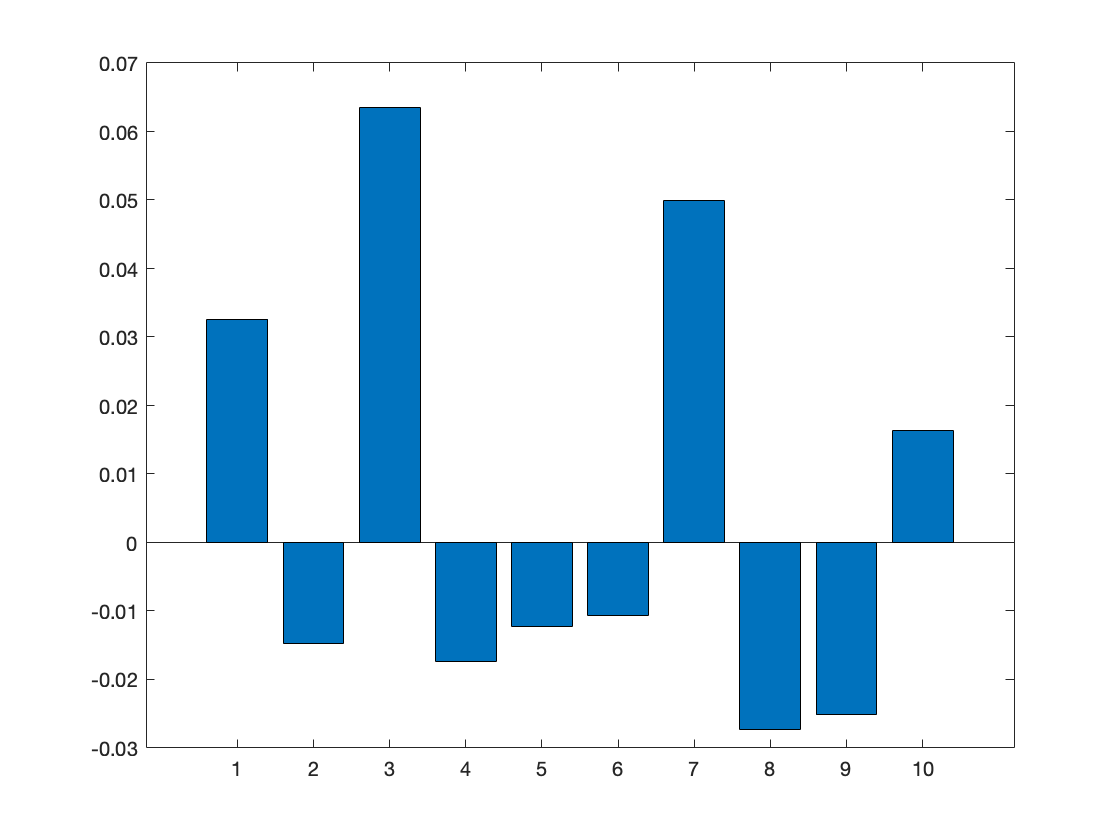

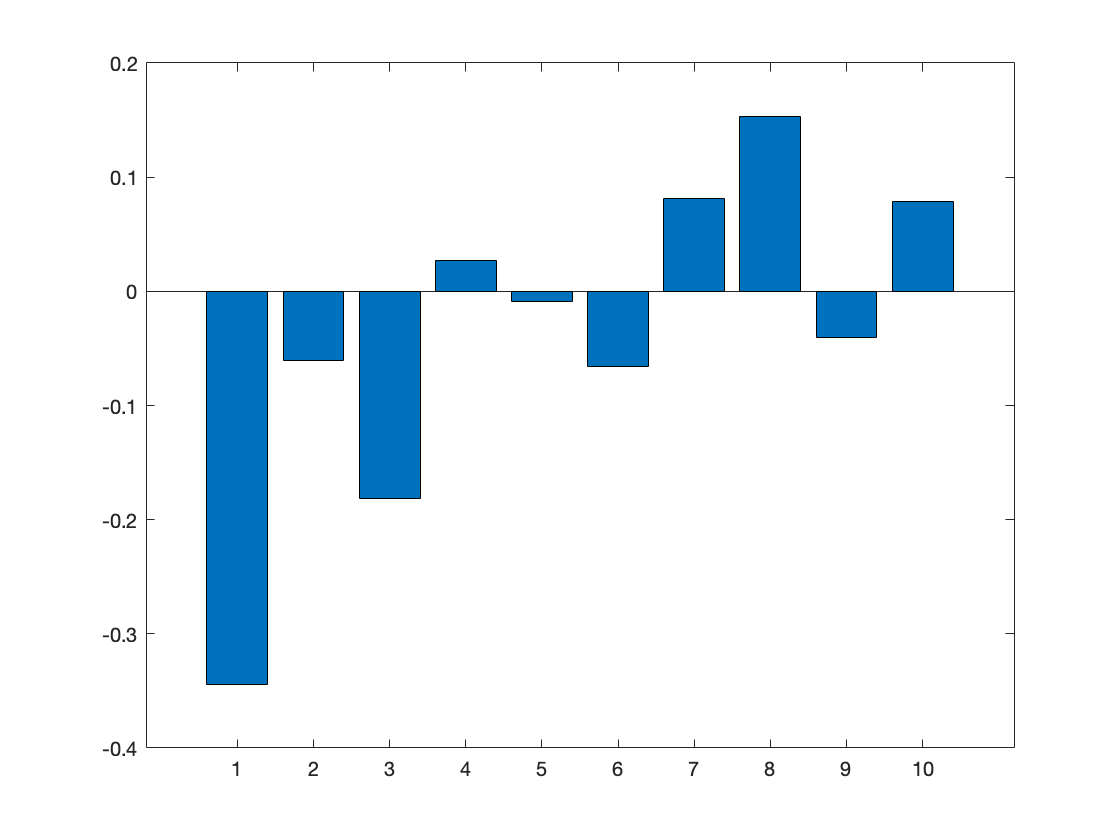


% post_pca_rho = corr([score Z_Feats']);
post_pca_rho = corr(score,Z_Feats');
num_params = length(Params(:,1));

for i = 1:length(post_pca_rho)
    figure
    bar(post_pca_rho(:,i))
end

% 
% %%
% NewScore = Xcentered';
% NewScore = score';
% for i = 1:length(NewScore(:,1))
%     figure
%     scatter(NewScore(i,:),Z_Feats(1,:));
% end
%     



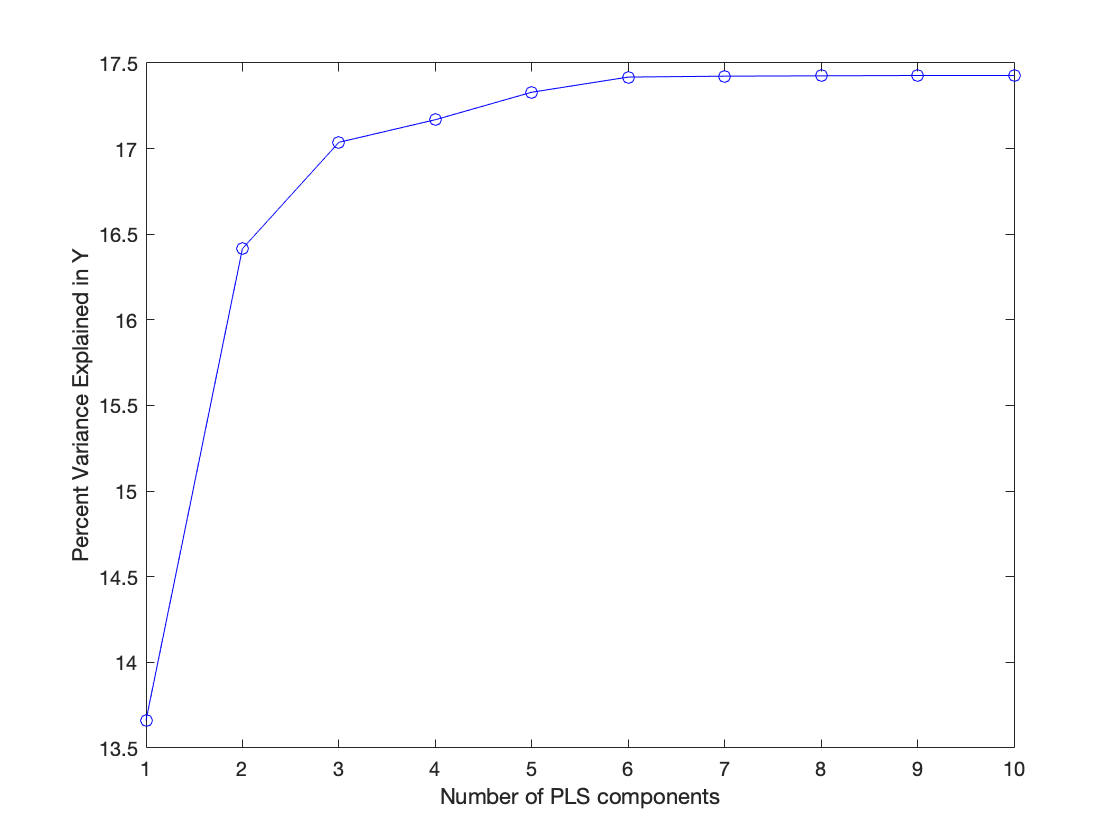

% 
% for i = 1:length(Xscores(1,:))
%     figure
%     scatter(Xscores(:,i),Yscores(:,i))
% end
% NaNIndex = isnan(NormFeats);
% NormFeats(NaNIndex) = 0;
% InfIndex = isinf(NormFeats);
% NormFeats(InfIndex) = 0;
[Xloadings,Yloadings,Xscores,Yscores,betaPLS,PLSPctVar] = plsregress(NormParams',NormFeats(8,:)',10);
[RXloadings,RYloadings,RXscores,RYscores,RbetaPLS,RPLSPctVar] = plsregress(NormParams',NormFeats(25,:)',10);
plot(1:10,cumsum(100*PLSPctVar(2,:)),'-bo');
xlabel('Number of PLS components');
ylabel('Percent Variance Explained in Y');

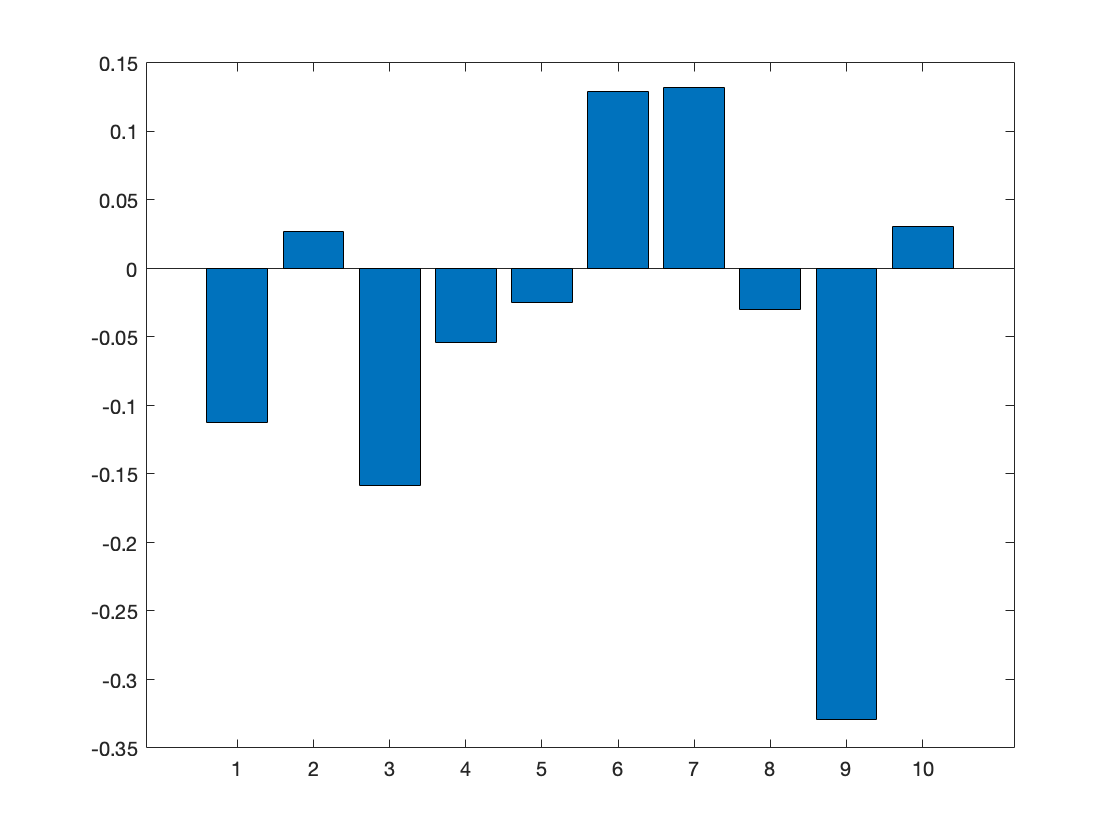

figure
% subplot(7,1,1);
bar(betaPLS(2:end,1));

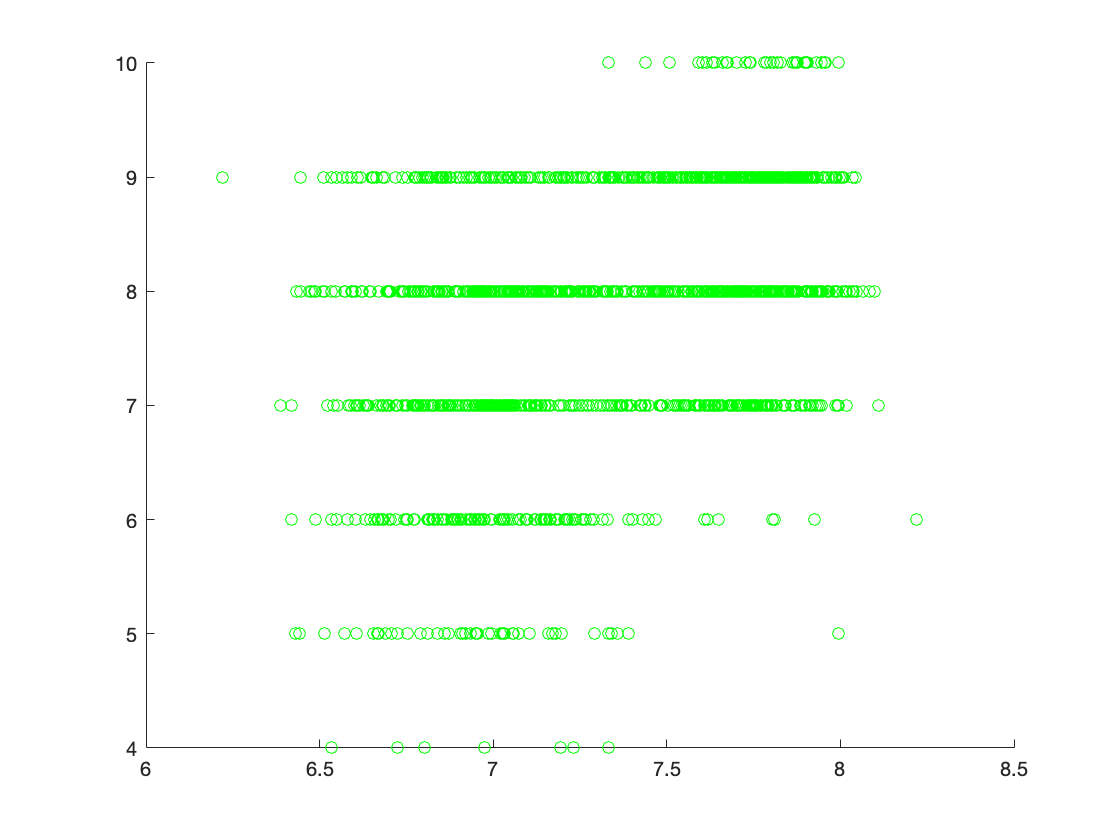


[n,p] = size(NormParams');
% yfitPLS = [ones(n,1) NormParams']*betaPLS;
for i = 1:length(Params(:,1))
    [Z_good, mu, sigma] = zscore(Params');
    STD = std(Params(i,:));
    NormParams(i,:) = Params(i,:)./STD;
end
% ZParams = ((NormParams'-mu)./sigma);
ZParams = Z_good;
yfitPLS = [ones(size(NormParams',1),1) (NormParams')]*betaPLS;
RyfitPLS = [ones(size(NormParams',1),1) (NormParams')]*RbetaPLS;
scatter(yfitPLS,Feats(1,:),'green')

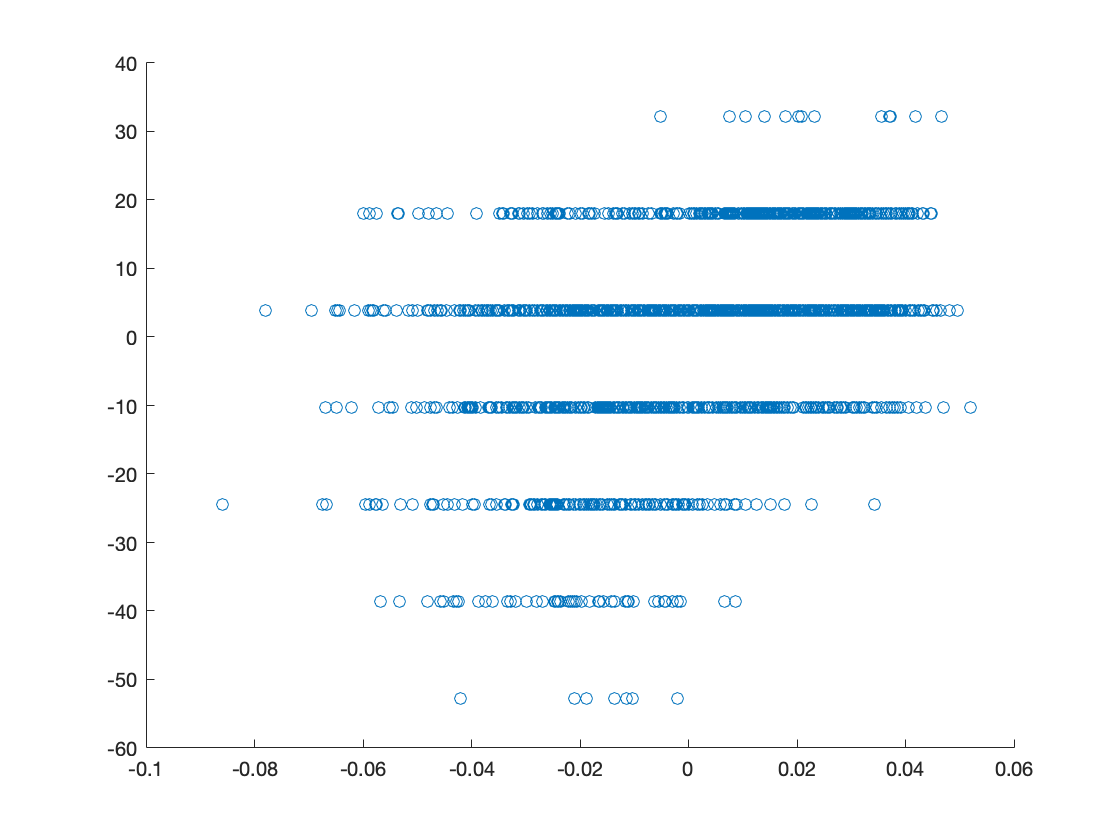

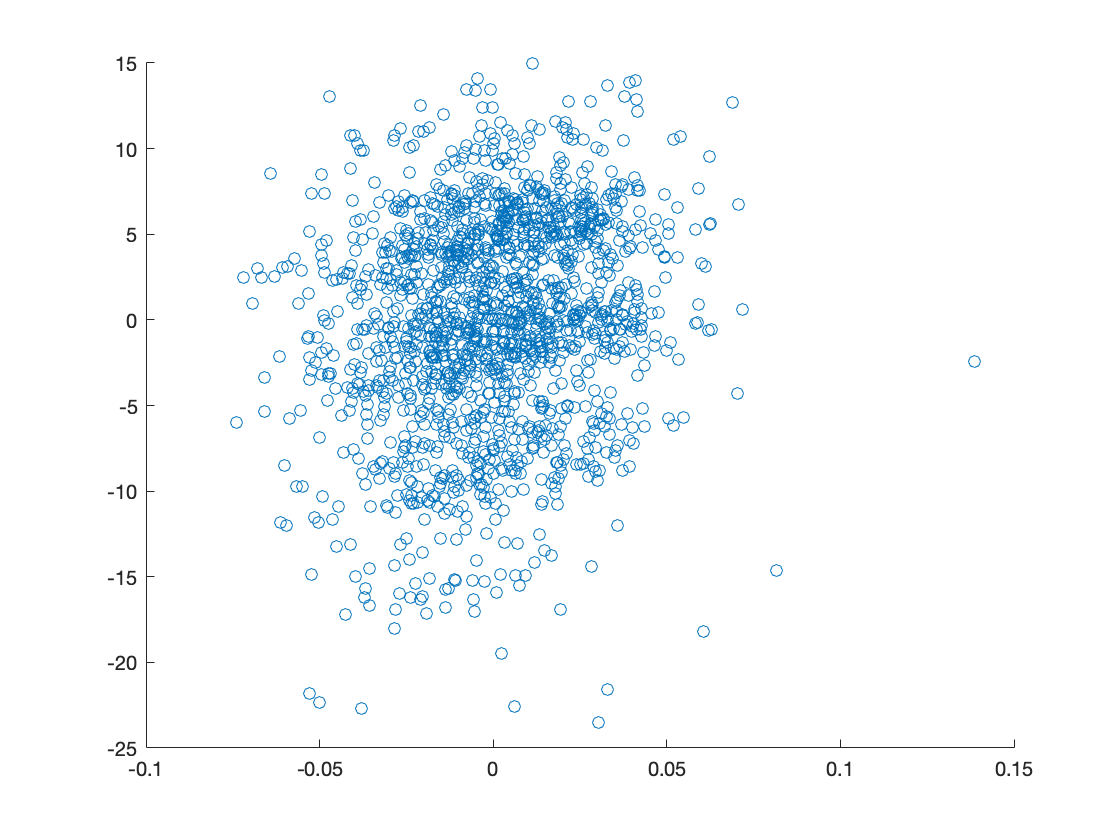

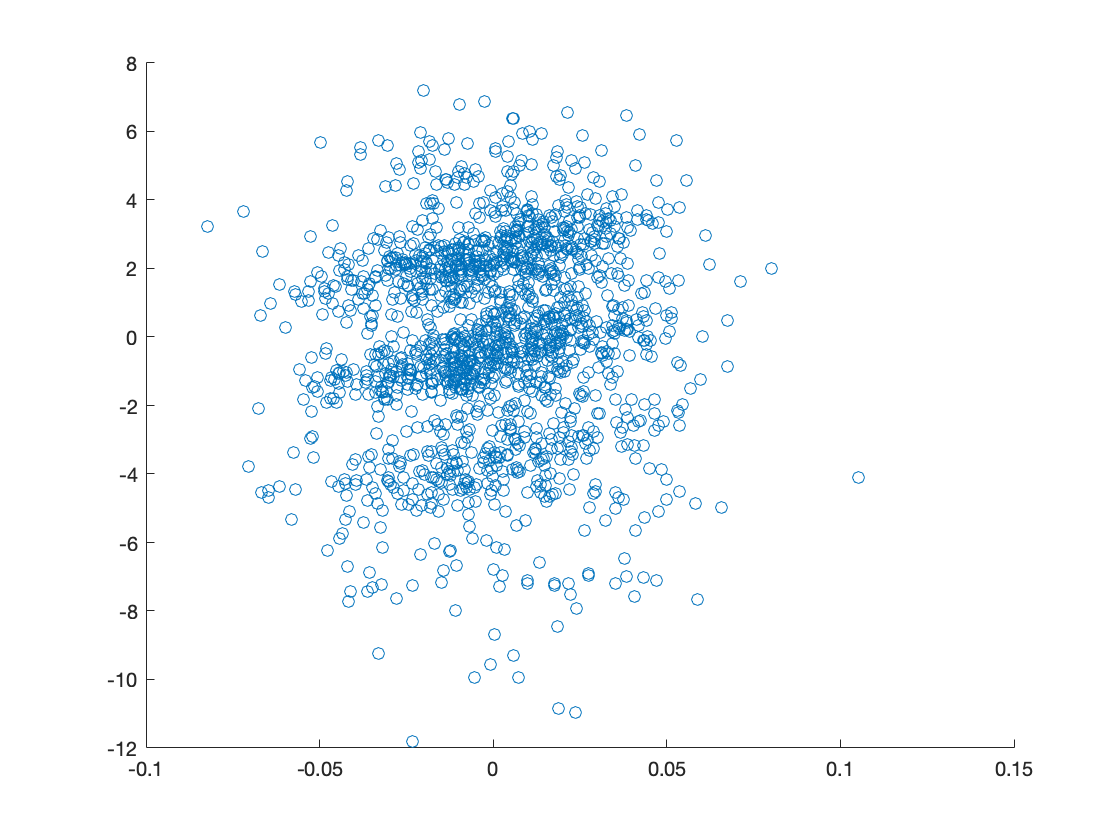

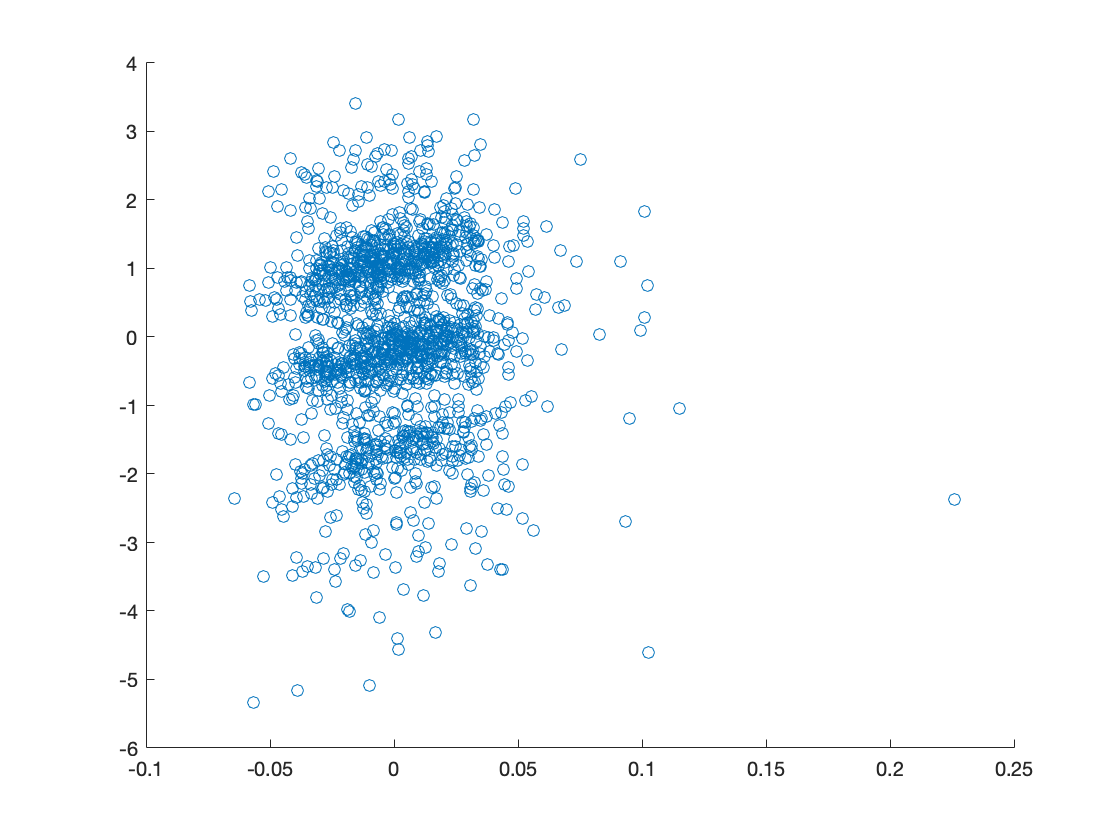

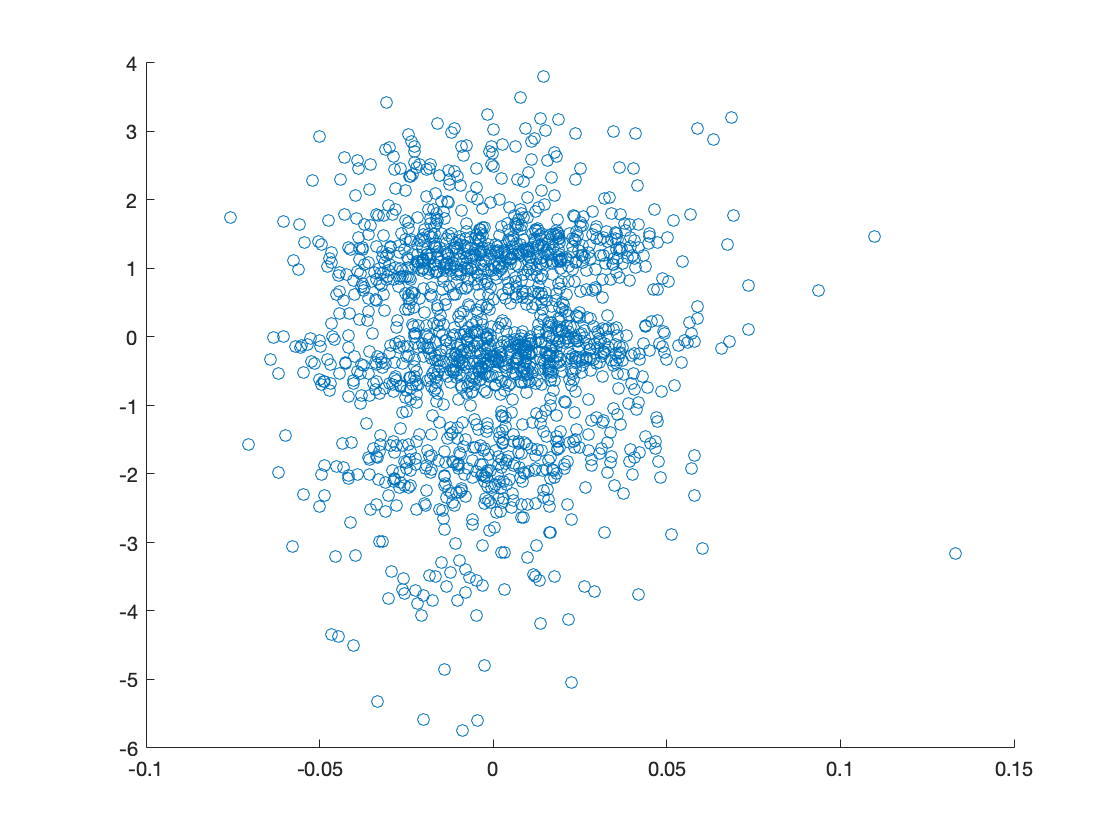

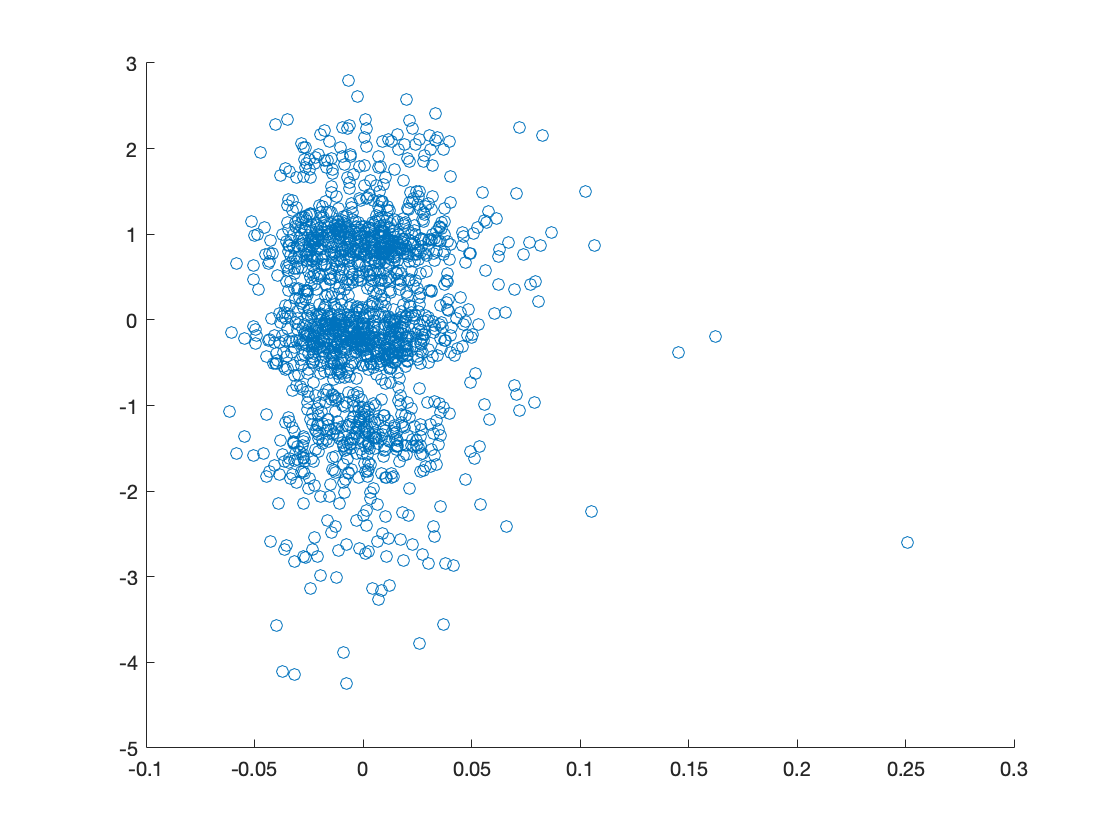

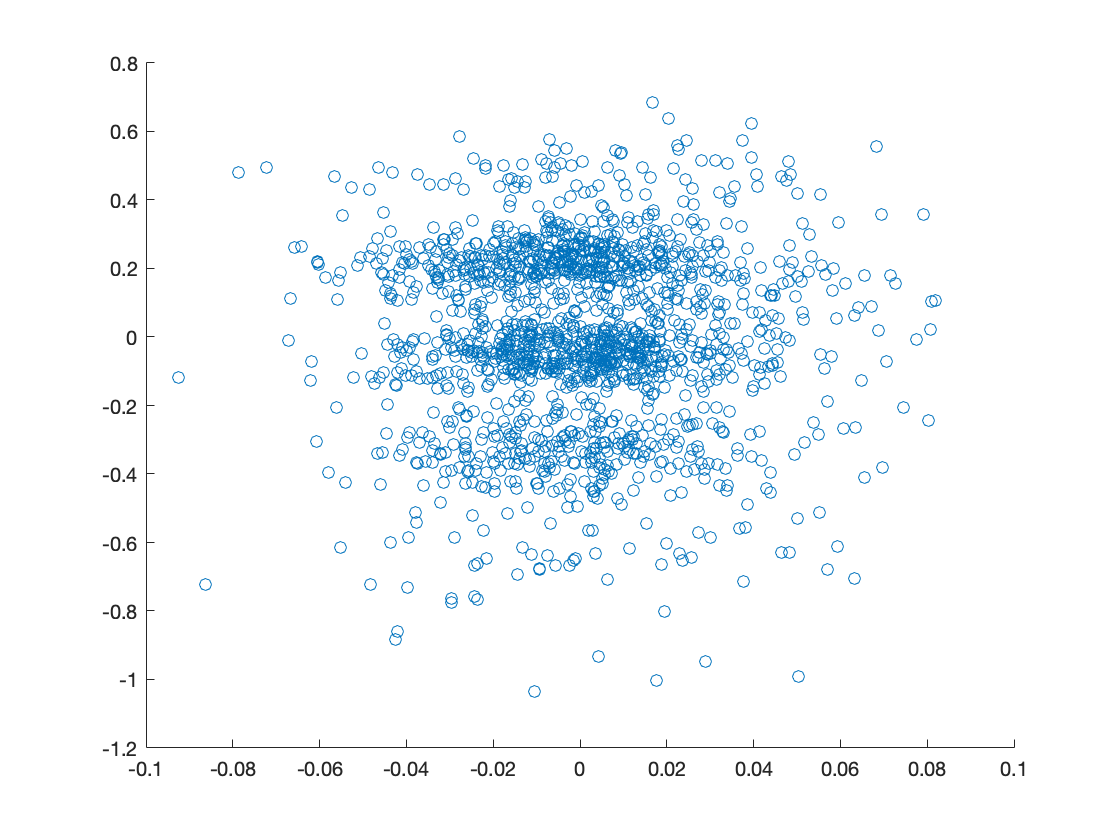

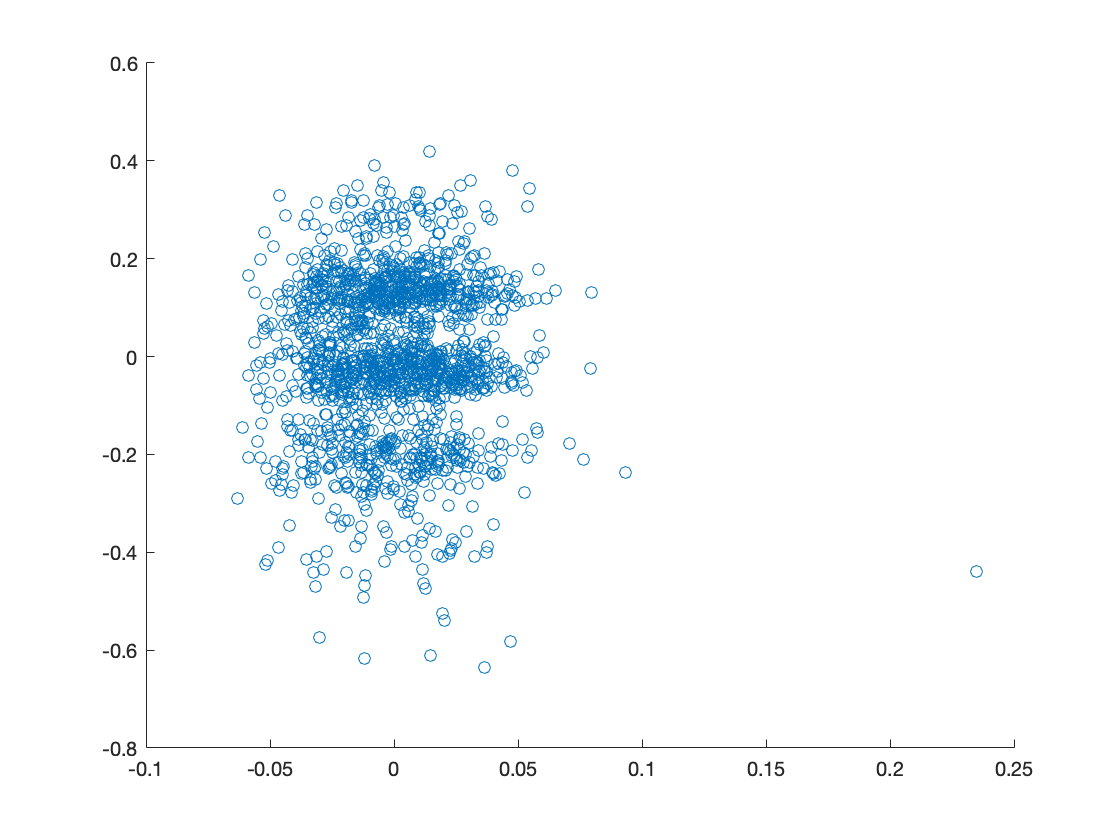

for i = 1:length(Xscores(1,:))
    figure
    scatter(Xscores(:,i),Yscores(:,i))
end

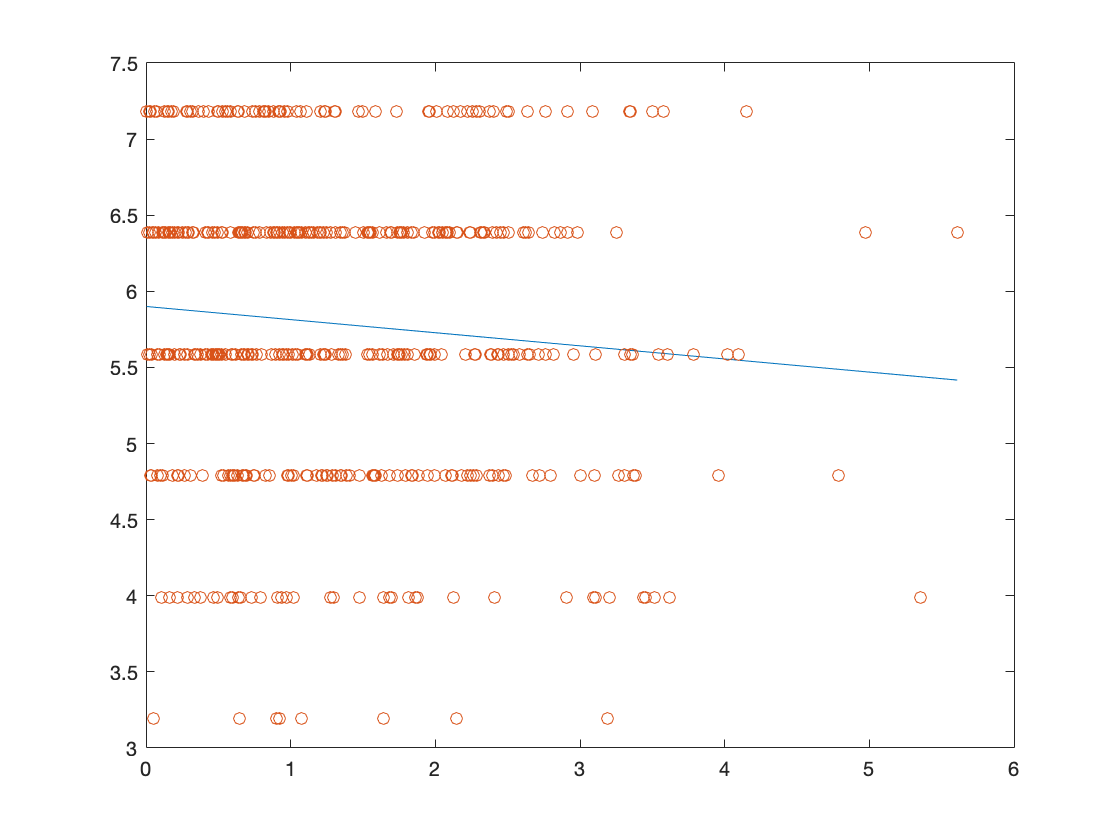

% Param = 1;
% Feat = 1;
% coefficients = polyfit(NormParams(Param,:), NormFeats(Feat,:), 1);
% yFitted = polyval(coefficients, NormParams(Param,:)); % yFitted will be at the 3 points where x is.  There will be 3 yFitted values.
% % If you want a lot more points, you can pass in more x to polyval():
% xFit = linspace(min(NormParams(Param,:)), max(NormParams(Param,:)), 1000); % 1000 points.
% yFitted = polyval(coefficients, xFit);
% 
% figure
% plot(xFit,yFitted)
% hold on
% scatter(NormParams(Param,:),NormFeats(Feat,:))

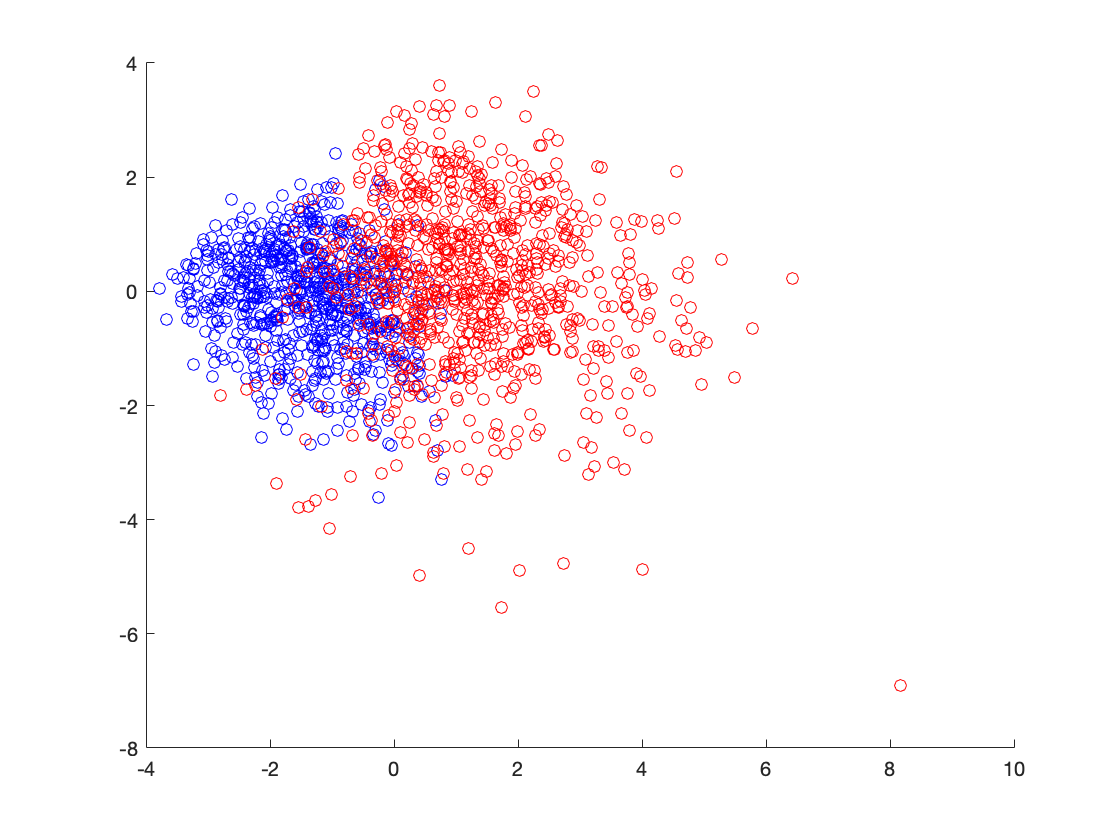

figure
scatter(score(1:ShamNum,1),score(1:ShamNum,2),'b')
hold on
scatter(score(ShamNum+1:end,1),score(ShamNum+1:end,2),'r')